## League Of Legends Toxicity Paper

clear;

## Modeling Question and Categorization

The research question is:** “What rate does toxicity with enemies need to spread in League of Legends for 50% of the total players to become toxic by the end of 10 games?” **This modeling question represents a new way to understand online gaming environments. We categorized the question as “Specific” for specificity and “Indirect” for action, because our question looks for an exact number for spread, which is why it is specific specificity, but it is not something we can change directly, which is why it is indirect for action. Specificity ensures a focused investigation, while the indirect action allows for a more disconnected exploration of how toxicity might spread through a gaming community. 

## Importance and Interest

The significance of this research extends far beyond a simple academic exercise, touching on an increasingly relevant social phenomenon in the modern age. With the massive growth of online gaming, which has become globally recognized, understanding the mechanisms of toxic behavior has never been more crucial. The research aims to trace how individual instances of frustration can quickly become widespread. By examining how toxic interactions spread like an infection spreading, the study provides insights into how the online gaming community interacts with itself. With this data, we could potentially develop a more effective strategy for maintaining positive social interactions online.

## **Validating Importance of Model**

Although our model may seem to be recreatable using a simple compounding interest formula, our model accounts for various parameters that cannot be demonstrated using the compound interest formula. These parameters include creating a beta distribution that assigns every player a "patience level" that is around 40% (DailyMail), which would create a sort of randomness in the model we have, which cannot be shown in the very uniform formula that compound interest shows. Our model also accounts for the fact that the more a person plays, the easier it is to become toxic, which is why we sample from a beta distribution that would skew more right slightly every time step, which would increase the anger rates of every person. By having these sorts of realistic parameters in our model, it makes it easy to track any changes that may happen in the real world, unlike a compound interest fomrula. Also, the model allows for finding different patience levels (beta) that can be found in different communities (i.e different countries, different games, etc), allowing for this model to be applied to many different situations.

## Background Information and References

Our research synthesis matrix compares information from multiple sources, creating an understandable comparison of different sites' views on toxicity in gaming communities. The investigation reveals that more than half of all gamers report experiencing "gamer rage," with League of Legends being a particularly intense environment for such interactions (ActivePlayer). The synthesis matrix illuminates several themes that pertain to the problem proposed in the modeling question. First, the prevalence of competitive gaming creates a high-pressure environment where emotion can quickly take control. Competitive modes, skill-based matchmaking, and the inherent pressure to perform create a perfect environment for toxic interactions (ResearchGate). The sources consistently highlight how lack of teamwork, intense competition, and the anonymity of being online can drastically lower social inhibitions.

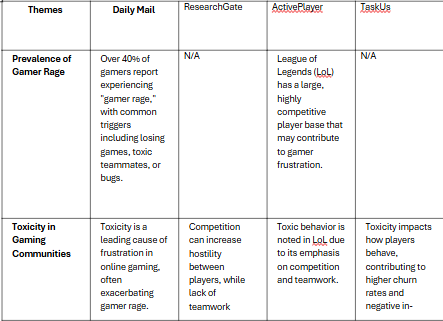

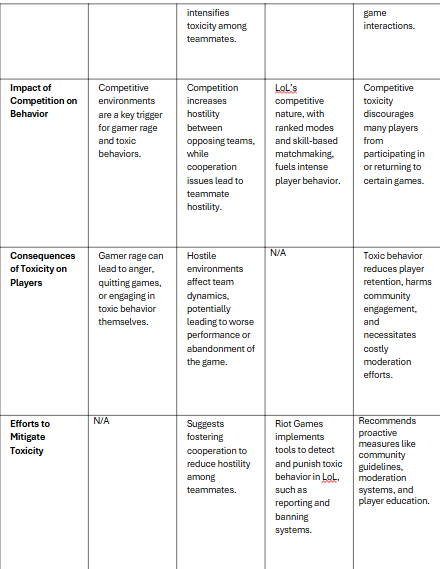

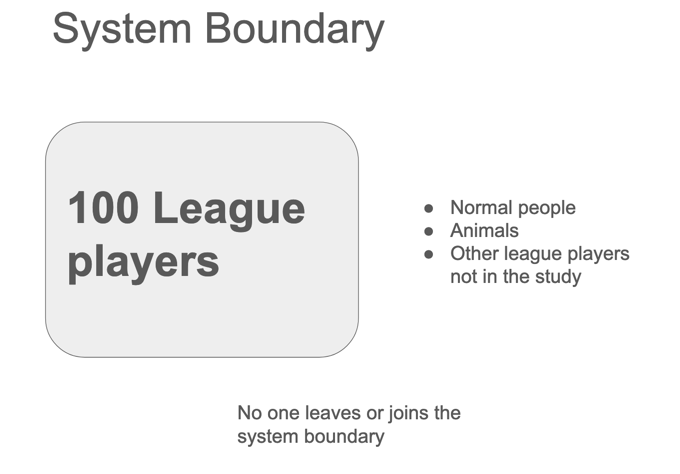

## **Action State Equations**

Susceptible is just subtracting the infected and recovered from a matrix of ones. Later we sum up the matrix to get the ending amount of susceptible people. (People do not go from recovered to susceptible, toxic to jolly) 

`   Sh = ones(dim, T) - Ih - Rh;`

`% Infect non-recovered individuals`

`% Finds infected and newly infected people and puts them together, also making sure they aren’t already recovered (so they don’t get infected again)`

`       I = I | v_infect & (~R);`

`% Putting together recovered and infected to recovered (making sure that they were already infected and then got recovered) `

`       I = I & (~R);`

`Deterministic and Random Variables:`

`Deterministic: # of total people, # of people per game, # of rounds`

`Random: Randomly sampled beta values for anger level for each person (how easy it is to get angry, same throughout the whole rounds), Increasing (every round), but randomly sampled beta values for anger threshold (how easy it is to get angry)`

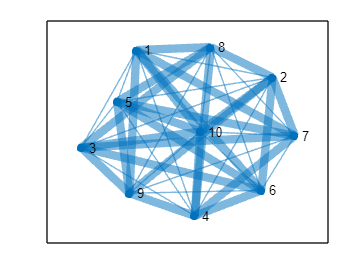

TotEnd = zeros(10,1);
count = 1;
for k = 0:0.05:1
    Average = 0;

gameSize = 10;
baseAnger = .05;
angerWithEnemy = k;

% 10 separate graphs for 10 games 
connections = groupConnections(gameSize, baseAnger, angerWithEnemy);
end
Graph_leaky = graph(connections); 
% 1 -  5 is strongly connected to enemies 6 - 10,
% but 1 - 5 are not strongly connected to one another and same for 6 - 10

figure();
LWidths = 5 * Graph_leaky.Edges.Weight / max(Graph_leaky.Edges.Weight);
plot(Graph_leaky, 'LineWidth', LWidths)

## **System Boundary and Conceptual Framework**

Our model represents a computational experiment focused on a closed system of 100 players, creating an environment to explore the dynamics of toxicity spread. By defining a clear system boundary, we isolate the interactions that might cause toxic behavior, excluding external variables, such as other players or people calming down, that could complicate our understanding. This approach allows a simplified understanding of connectivity in League of Legends games, and how they lead to toxicity.

## **Key Assumptions and Theoretical Foundations**

The model relies on several assumptions. We assume that players remain within the system throughout the simulation, creating a closed social environment. One critical assumption is that a player, once becoming toxic, remains in that state, which allows us to explore the cumulative and the exponential spread caused by toxicity in the gaming community. By representing toxicity spread through a beta distribution curve that looks like a normal curve with a meanof 0.4, we assume that people get angry 40% of the time. Our model's assumptions are reasonable because they simplify complex social dynamics while capturing the key behavioral patterns of online gaming: players in competitive environments are likely to experience frequent frustration, toxic interactions can leave lasting effects, and a closed system allows us to track how negative behaviors might systematically spread through the same player group.

## **Model States and Interaction Dynamics**

At its core, the model recognizes two fundamental states of player behavior: the happy player and the **toxic** player. This simplification provides a clear way to show social interactions. The model seeks to understand how the constant change of connections (every match) and randomly distributed anger levels (beta distribution) can change a neutral player to a toxic one.

## Model Development and Verification

The research uses a parameter sweep, focusing on interactions between enemy team members - a context known for heightened emotional tension. This approach allows the model to account for one of the most anger-inducing factors in humans (when you lose or get killed by the enemy L). By using a beta distribution with parameters, a=42 and b=58, we found the toxicity spread rates, sweeping from 0 to 1 in 0.05 increments. According to DailyMail, we found that the base anger rates were 0.05 and a mean toxicity probability of 0.4.

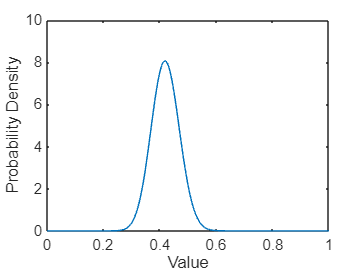

people = 100;
% Initialize distribution

a = 42; % First shape parameter
b = 58; % Second shape parameter
assert(a > 0 && b > 0, 'Shape parameters a and b must be positive.');

pd_beta = makedist('Beta', 'a', a, 'b', b);

% Visualize
x = linspace(0, 1, 200);
pr = pd_beta.pdf(x);
figure();
plot(x, pr)
xlabel('Value')
ylabel('Probability Density')

% title('Beta Distribution: a=8, b=8')

R = betarnd(42, 58, people, 1)

R =     0.5213
    0.4417
    0.3539
    0.4636
    0.5238
    0.4745
    0.4328
    0.4506
    0.4834
    0.4800


% gameSize = 10;
% baseAnger = .05;
% angerWithEnemy = .2;
% 
% % 10 separate graphs for 10 games 
% connections = group(gameSize, baseAnger, angerWithEnemy);
% 
% % There are 2 teams, so make a for loop that goes through it and strongly
% % connects the one person to the other team
% 
% connections
% 
% Angry = zeros(1,100);
% % randomly sample from 1,100)
% Angry(1) = 1
% AngerRate = transpose(R)


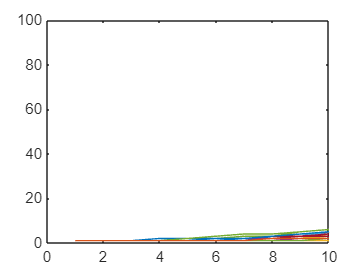

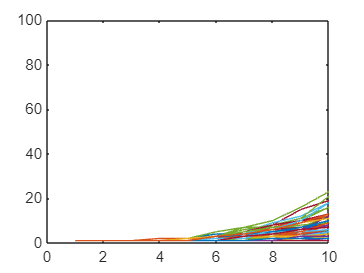

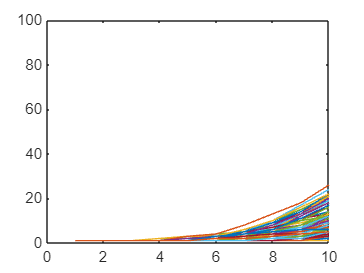

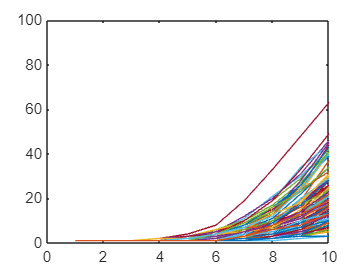

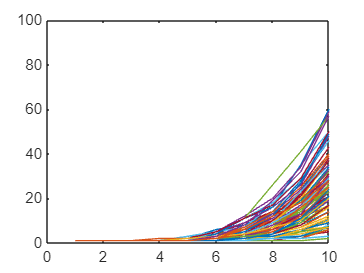

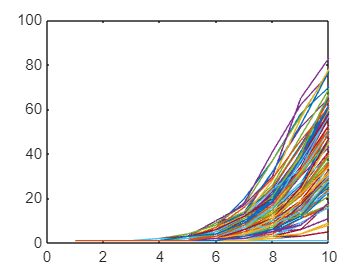

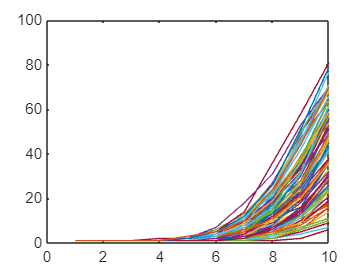

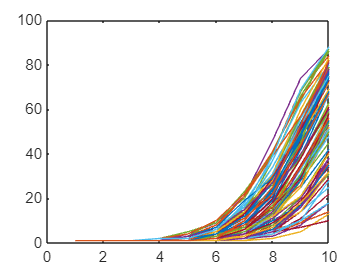

% %[Sh, Ih, Rh] = simulate_absir(M, Iv0, T recovery_rate)
% numTimeSteps = 10; 
% numGames = 10;
% n = 100;  % Total number of elements
% size = [10 10];  % Desired matrix dimensions
% R = transpose(R);
% R = reshape(R, 10, 10);
% IhOne = zeros(10);
% state = zeros(100,numTimeSteps+ 1);
% state(:,1) = Angry'
% totangry = zeros(100,1);
% figure;
TotEnd = zeros(10,1);
count = 1;
for k = 0:0.05:1
    hold off;
    Average = 0;
gameSize = 10;
baseAnger = .05;
angerWithEnemy = k;

% 10 separate graphs for 10 games 
connections = groupConnections(gameSize, baseAnger, angerWithEnemy);


% There are 2 teams, so make a for loop that goes through it and strongly
% connects the one person to the other team

connections;

Angry = zeros(1,100);
% randomly sample from 1,100)
Angry(1) = 1;
AngerRate = transpose(R);
%[Sh, Ih, Rh] = simulate_absir(M, Iv0, T recovery_rate)
numTimeSteps = 10; 
numGames = 10;

assert(mod(people, gameSize) == 0, 'Number of people must be divisible by the game size.');
assert(people > 0, 'Number of people must be positive.');

n = 100;  % Total number of elements
size = [10 10];  % Desired matrix dimensions
R = transpose(R);
R = reshape(R, 10, 10);
IhOne = zeros(10);
state = zeros(100,numTimeSteps+ 1);
state(:,1) = Angry';
totangry = zeros(100,1);
figure;
for j = 1:100
for i = 1: numTimeSteps
    % one time step
    alpha = betarnd(10*i, 100-10*i, 1, 1);
    shuffle = randperm(n);
    matrix = reshape(shuffle, size);
    % R(matrix(:,i)); NEEDS TO BE USED LATER
    for game = 1:numGames
        shuffled_angry = state(matrix(:,game),i);
        shuffled_r = R(:,1);
        % only Ih is important because we want to see how many people get
        % infected total
        % 2 because 1 is the base state, 2 is if one round went
        [sh, Ih, rh] = simulate_absir(connections, shuffled_angry, 2, 0, shuffled_r, alpha); % recover rate is 0, they stay angry the whole time
        
        IhOne(:,game) = Ih(:,2);
        a = zeros(100,1);
        poop = shuffle';
        a(poop) = reshape(IhOne, 100,1);
        state(:,i+1) = a;
    end
end

totangry(j) = sum(state(:,11));
plot(sum(state))
hold on;
xlim([0 10]);
ylim([0 100]);

Average = Average + sum(state(:,11));
end

TotEnd(count) = Average/people;
count = count + 1;
end




half = zeros(length(TotEnd),1);
assert(length(half) == length(TotEnd), 'Half array must match the size of TotEnd.');

for i = 1:length(TotEnd)
    half(i) = abs(50 - TotEnd(i));
end

val = min(half);
index = find(half==val)

index = 6

% half(index);

BestBeta = .05*index

BestBeta = 0.3000

`Explaining parameters: `

`Beta Beta distribution for each person, anger rate, mean at .4`

`Graph: Connections between players in any of the game and varying connection for same team or different team`

`Alpha: Beta distribution for the overall anger threshold which increases every round because people will get angrier the more games they play`

`Shuffled_angry & Shuffled_R: Randomly shuffle 100 people (whether they are infected (toxic, 0/1 and each person's randomly sampled beta) into 10 groups of 10 every round`

`NumTimeSteps: Total matches that each person plays`

## Results and Analysis

Through parameter sweeping, we found a pattern in toxicity transmission. The research reveals that a toxicity spreading rate between 0.25 and 0.3 most consistently results in approximately half the players becoming toxic by the end of 10 matches.

The results account for the inherent randomness in social interactions, providing a range rather than a single definitive value. This approach acknowledges the complexity of human behavior, recognizing that social phenomena cannot be reduced to deterministic models. The consistent emergence of the 0.25-0.3 range suggests a potential "value" in social contagion, around 50 of the 100 players will be toxic after 10 games, which answers our modeling question of what the toxicity spread rate should be to have 50% of the initial population become toxic after 10 games.

## Interpretation and Findings

Our analysis reveals toxicity within competitive gaming environments. The discovery that toxicity can spread to half a population within just ten matches highlights the fragility of positive social interactions and the potential for rapid behavioral deterioration.

The 0.25-0.3 transmission rate range becomes a critical threshold, representing when around half of the 100 people get angry. Beyond this point, toxic behavior becomes self-reinforcing, creating a feedback loop that ends with a toxic community. This insight has significant implications for community management, game design, and understanding social contagion mechanisms.

function [connections] = groupConnections(numPeople, baseAnger, angerWithEnemy)
    connections = ones(numPeople,numPeople) - eye(numPeople);
    connections = connections * baseAnger;
    for i = 1: numPeople/2
        for j = numPeople/2 + 1: numPeople
            connections(i,j) = angerWithEnemy;
        end
    end
    for i = numPeople/2+1: numPeople
        for j = 1: numPeople/2
            connections(i,j) = angerWithEnemy;
        end
    end
end

